Porównajmy dokładność całki obliczanej metodą trapezów i metodą Simpsona (parabol).

clear all;
close all;
%zwybór funkcji, z której będzie obliczana całka
syms f(x)
f(x)=x^6+3*x^4-2*x

$$f(x) = x^{6}+3\,x^{4}-2\,x$$



%Uruchom w domyślnym przedziale
deafVal=true;
%umieszczanie wartosci calki na wykresach
intVis=true;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%dobór domyślnego przedziału dla wybranej funkcji
if deafVal==true
    if strcmp(string(char(f(x))),"sin(x)")
        a=0
        b=10
    end
    if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        a=-3
        b=4
    end
    if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        a=-1
        b=1
    end
    if strcmp(string(char(f(x))),"3*x + x^2 - 5")
        a=-3
        b=2
    end
    if strcmp(string(char(f(x))),"exp(x)")
        a=1
        b=5
    end        
else
    a=input("Podaj lewy kraniec przedzialu:")
    b=input("Podaj prawy kraniec przedzialu:")
    if a>=b
        display("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

a = -1

b = 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%obliczenie całki analitycznie (na wyrażeniu symbolicznym):
calka_dokladna=double(int(f,a,b))

calka_dokladna = 1.4857

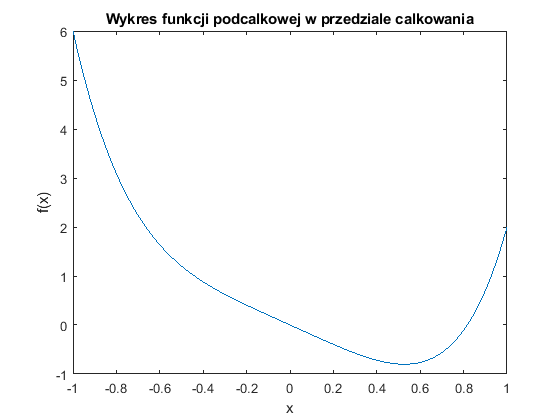


%zmiana wyrażenia symbolicznego na funkcję anonimową:
f=matlabFunction(f); 

%rys. wykresu funkcji:
x1=linspace(a,b,abs(b-a)*100);
figure()
plot(x1,f(x1))
title 'Wykres funkcji podcalkowej w przedziale calkowania'
xlabel 'x'
ylabel 'f(x)'

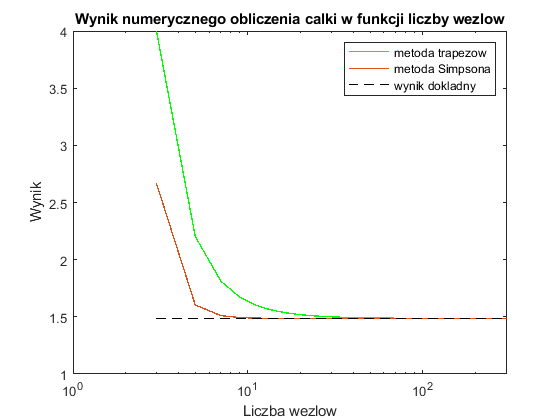


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Wyznaczenie błędu cąłkowania metodami trapezów i Simpsona w zależności od liczby wezłów:
maxNodNr=300; %max rozpatrywana liczba węzłów
ptsOnPlot=50; %liczba węzłów wybrana do obliczeń z przedziału (3;maxNodNr)
x2=2*ceil(logspace(0,log10(maxNodNr/2),ptsOnPlot))+1; %wyznacza liczby wezlow, dla ktorych zostanie wykonane obliczenie, tylko wartości parzyste, żeby uniknąć problemów z implementacją metody Simpsona przy krawedziach przedzialu

for k=1:numel(x2);      %wyznaczenie wartości całki - obie metody (w każdej iteracji dla innej liczby węzłów)
                        %x2(k) to liczba wezlow  
    h=(b-a)/(x2(k)-1);  %h to odleglosc miedzy wezlami

    %implementacja kwadratury zlozonej trapezow:
    calka_trapez(k)=0;
    for i=1:x2(k)-1
        aTemp=a+(i-1)*h;
        bTemp=a+i*h;
        calka_trapez(k)=calka_trapez(k)+h*(f(aTemp)+f(bTemp))/2;
    end

    %implementacja kwadratury zlozonej Simpsona
    calka_Simpson(k)=0;
    for i=1:(x2(k)-1)/2
        aTemp=a+(2*i-2)*h;
        bTemp=a+(2*i)*h;
        calka_Simpson(k)=calka_Simpson(k)+(bTemp-aTemp)/6*(f(aTemp)+4*f((aTemp+bTemp)/2)+(f(bTemp)));
    end
    
    %wyznaczenie bledu wzglednego dla obliczenia całki przy danej liczbie wezlow:
    blad_trapez(k)=abs((calka_trapez(k)-calka_dokladna)/calka_dokladna);
    blad_Simpson(k)=abs((calka_Simpson(k)-calka_dokladna)/calka_dokladna);
end
figure()
semilogx(x2,calka_trapez,'g',x2,calka_Simpson, x2, linspace(calka_dokladna,calka_dokladna,numel(x2)),'k--', 'lineWidth', 1)
title 'Wynik numerycznego obliczenia calki w funkcji liczby wezlow'
xlabel 'Liczba wezlow'
ylabel 'Wynik'
legend(' metoda trapezow', ' metoda Simpsona', ' wynik dokladny')

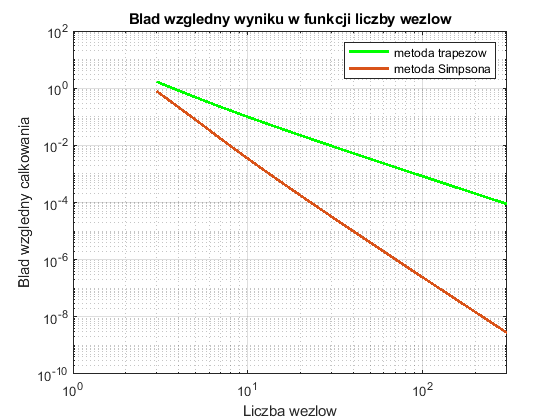

figure()
loglog(x2,blad_trapez,'g',x2, blad_Simpson, 'lineWidth', 2)
title 'Blad wzgledny wyniku w funkcji liczby wezlow'
xlabel 'Liczba wezlow'
ylabel 'Blad wzgledny calkowania'
legend(' metoda trapezow', ' metoda Simpsona')
grid on


%w ramach ćwiczenia zastanów się, czym różni się poniższy kod i czy działał
%by on poprawnie:
% for k=1:numel(x2);
%     h=(b-a)/(x2(k)-1);
%     pkt_l=(a:h:b-h); %lewe krańce podprzedziałów
%     pkt_r=(a+h:h:b); %prawe krańce podprzedziałów
%     pkt_2j=(a+h/2:h:b-h/2); %środki podprzedizałów
%     calka_trapez(k)=sum(f(pkt_l)+f(pkt_r))/2*h;
%     calka_simpson(k)=sum(f(pkt_l)+4*f(pkt_2j)+f(pkt_r))/6*h;
%     blad_trapez(k)=abs((calka_trapez(k)-calka_dokladna)/calka_dokladna);
%     blad_Simpson(k)=abs((calka_Simpson(k)-calka_dokladna)/calka_dokladna);
% end